# Independent Component Analysis of whole brain using Aya's EEG dataset

clear;

% ===============================================
% Compute ICA for each subject × condition × subtype
% ===============================================

clear; clc;

%% 1) Set your input/output roots
if exist('H:\', 'dir')         % Computer 1
    input_root  = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_root = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA_results\';
elseif exist('G:\', 'dir')     % Computer 2
    input_root  = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_root = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA_results\';
else
    error('Unknown system. Please adjust your paths.');
end

conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'

## Define for each "top‐down” condition the two subtype labels and the sheet names

subtypeInfo.P2.labels    = {'A','B'};
subtypeInfo.P2.sheetsA   = 'Audio onset with 500 ms tactile';
subtypeInfo.P2.sheetsB   = 'Audio onset with 2000 ms tactil';

subtypeInfo.P3.labels    = {'A','B'};
subtypeInfo.P3.sheetsA   = 'Audio onset with 500 ms tactile';
subtypeInfo.P3.sheetsB   = 'Audio onset with missing tactil';

% Start the parallel pool once at the beginning
try
    poolobj = gcp('nocreate'); % Get current parallel pool without creating one
    if isempty(poolobj)
        poolobj = parpool(); % Create a parallel pool with default settings
    end
catch err
    warning('Could not create parallel pool');
    warning('Running in serial mode instead');
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


  - Subtype X: 60 trials


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (28) is smaller than the number of channels (32).

Input data size [28,107520] = 28 channels, 107520 frames/nAfter PCA dimension reduction,
  finding 28 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 137 frames per ICA weight ((784)^2 = 107520 weights, Initial learning rate will be 0.001, block size 58.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -27.0606 to 30.6265
Reducing the data to 28 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step

Plotting...


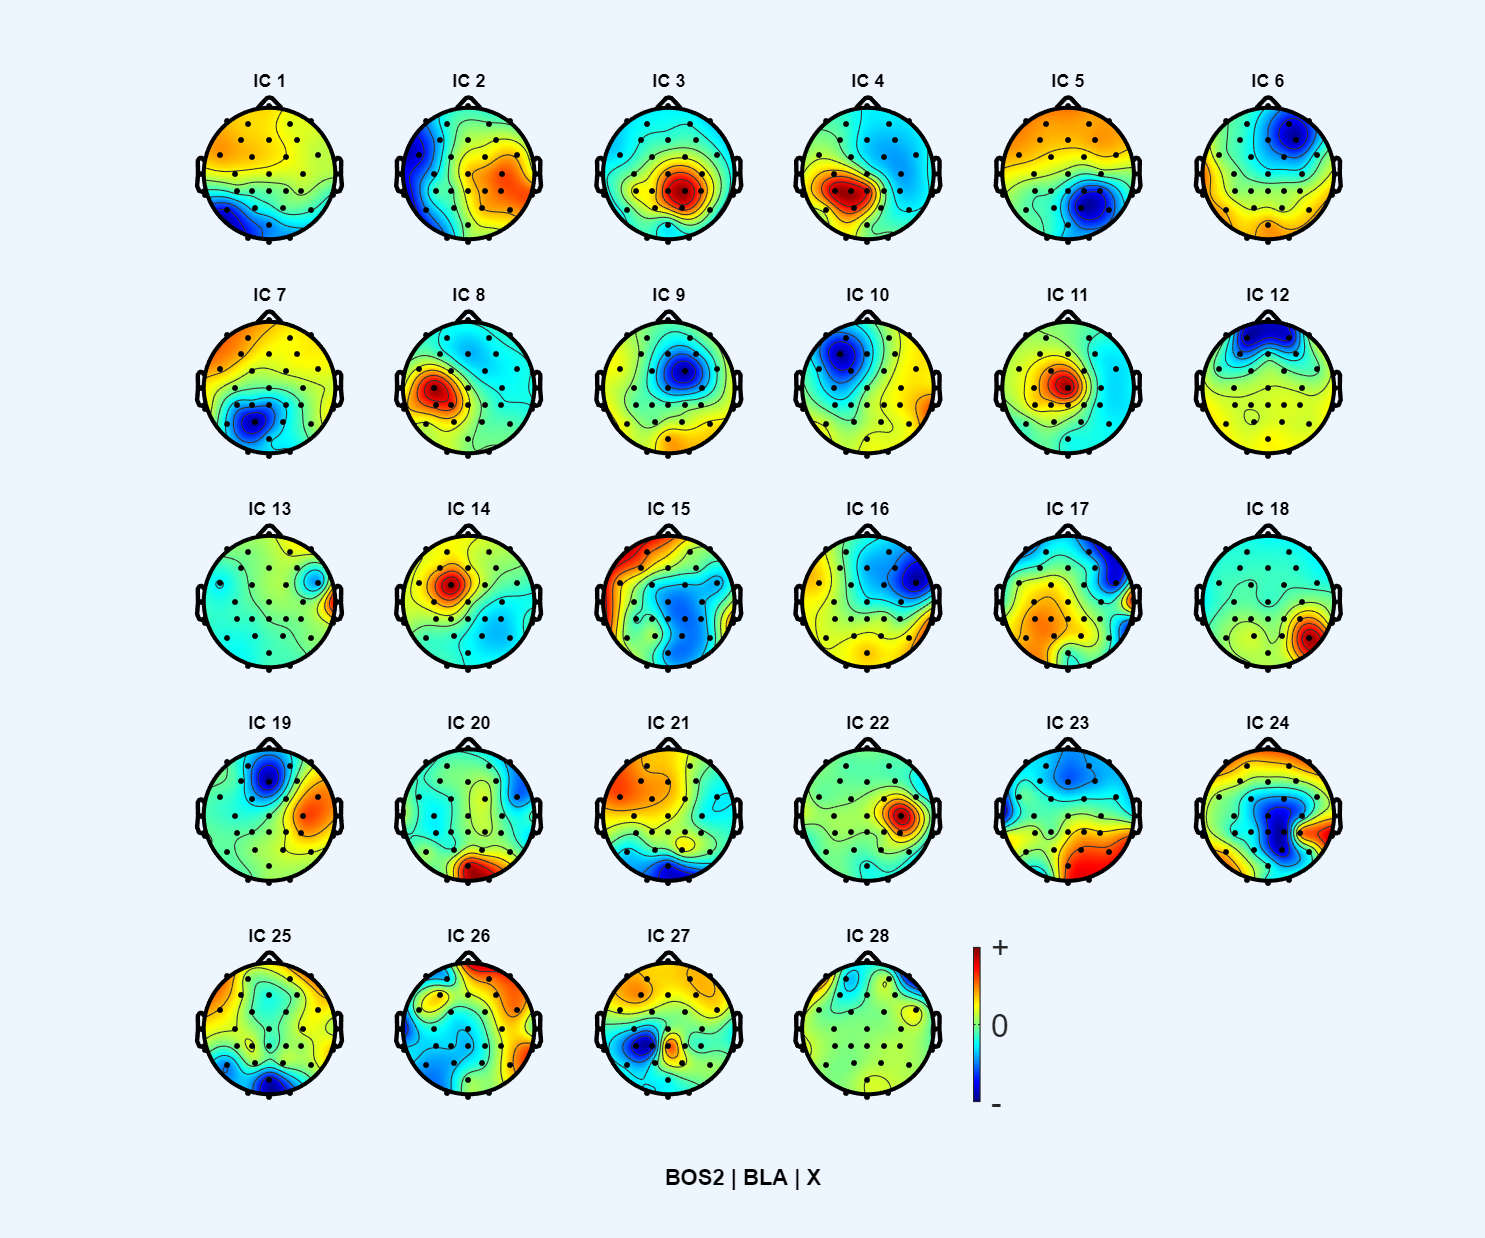

pop_loadset(): loading file H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'H:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


  - Subtype X: 60 trials


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (27) is smaller than the number of channels (32).

Input data size [27,107520] = 27 channels, 107520 frames/nAfter PCA dimension reduction,
  finding 27 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 147 frames per ICA weight ((729)^2 = 107520 weights, Initial learning rate will be 0.001, block size 58.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -7.50532 to 6.95026
Reducing the data to 27 principal dimensions...
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
step

Plotting...


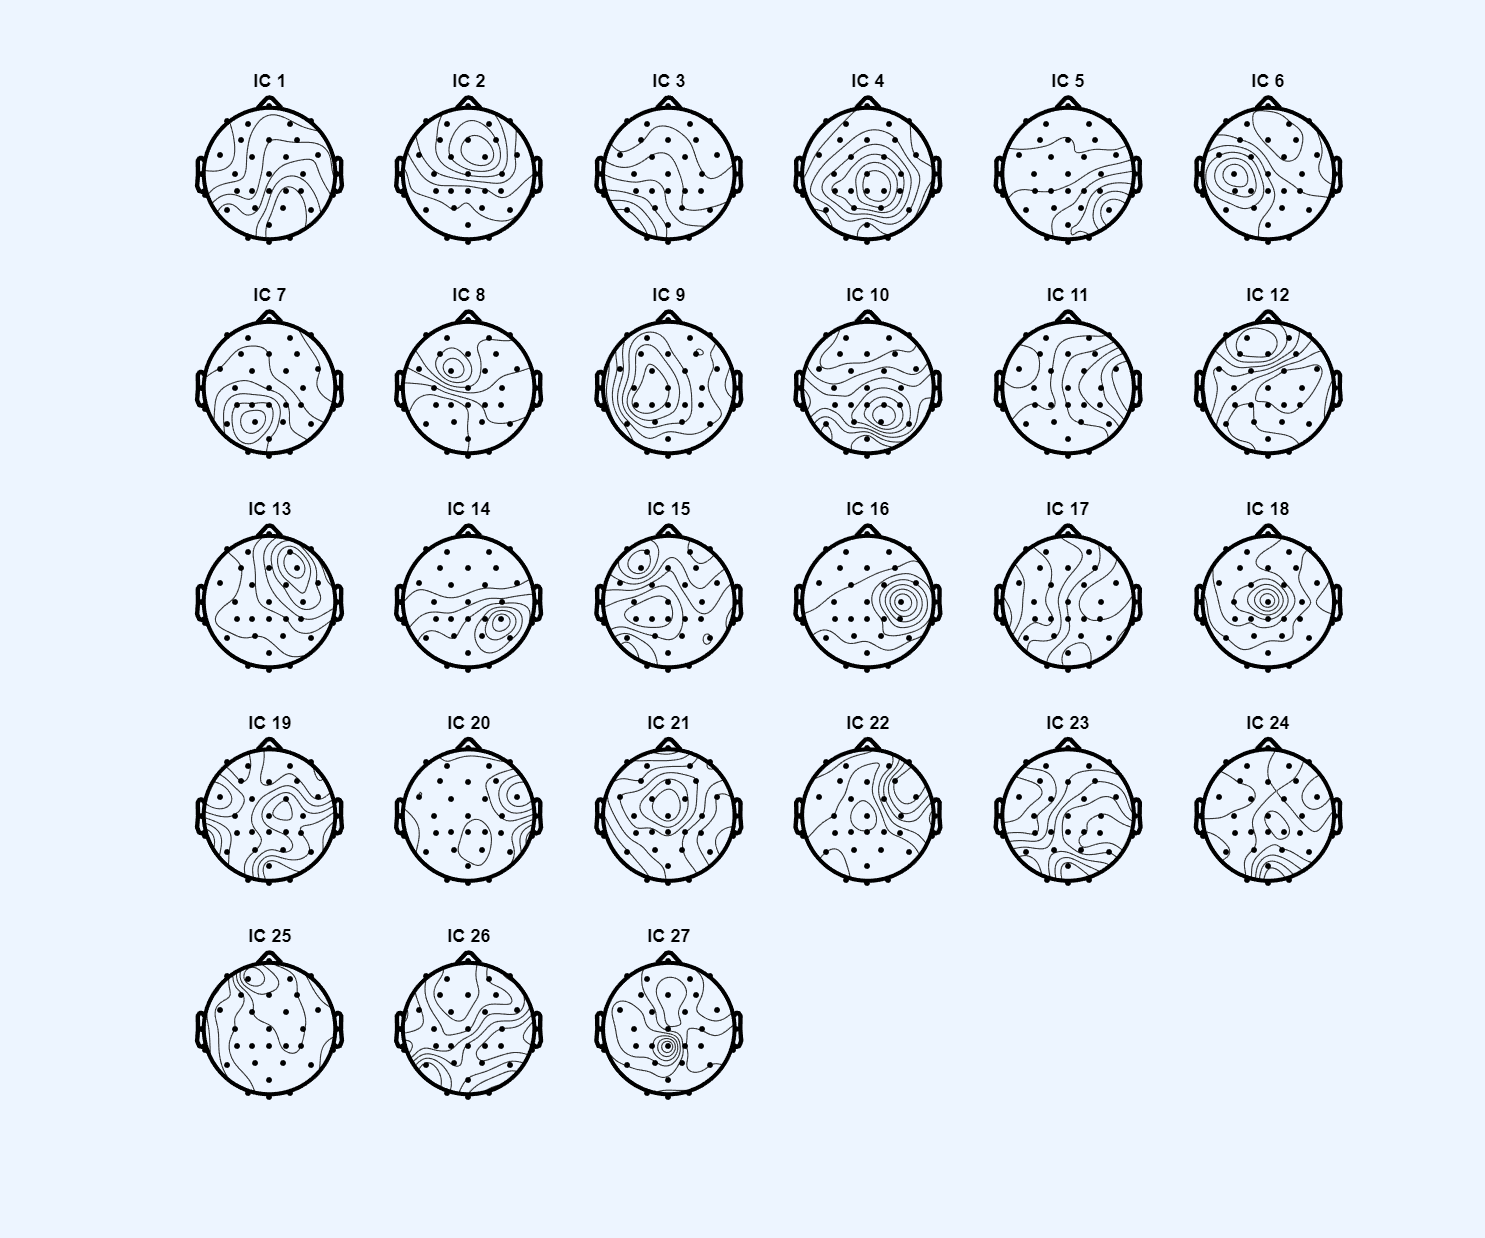

Index in position 2 exceeds array bounds. Index must not exceed 27.
Error in pop_topoplot (line 398)
                 tmpobj = topoplot( EEG.icawinv(:, arg2(index)), EEG.chanlocs, options{:} );

for j = 1:length(subjects)
    subject = subjects{j};
    for i = 1:length(conditions)
        condition = conditions{i};

        % Load EEG again to extract condition-specific data
        input_path_condition = fullfile(input_root, condition);
        set_files = dir(fullfile(input_path_condition, '*.set'));
        file_idx = find_subject_file(set_files, subject);
        file_path = fullfile(input_path_condition, set_files(file_idx).name);
        EEG_cond = pop_loadset(file_path);
        fs = EEG_cond.srate;

        %% 3.2) Define epoch list (odd vs even)
        if ismember(condition, {'BLA','P1','P2','P3'})
            epoch_trials = 1:2:EEG_cond.trials;
        else  % BLT
            epoch_trials = 2:2:EEG_cond.trials;
        end
        
        %% 3.3) Define sub‐conditions
        if strcmp(condition,'P2') || strcmp(condition,'P3')
            % read the excel once
            xls_path = fullfile(input_root,'Indexes for P2.xlsx');
            if strcmp(condition,'P3')
                xls_path = fullfile(input_root,'Indexes for P3.xlsx');
            end
            
            % read trial lists
            trialsA = intersect(epoch_trials, ...
                        readmatrix(xls_path,'Sheet', subtypeInfo.(condition).sheetsA));
            trialsB = intersect(epoch_trials, ...
                        readmatrix(xls_path,'Sheet', subtypeInfo.(condition).sheetsB));
            
            sub_labels = subtypeInfo.(condition).labels;
            trialLists = {trialsA, trialsB};
        else
            % Single “subtype” for BLA, BLT, P1
            sub_labels = {'X'};
            trialLists = {epoch_trials};
        end   
        
        %% 3.4) Loop over each subtype and run ICA
        for s = 1:numel(sub_labels)
            subtag    = sub_labels{s};
            selTrials = trialLists{s};
            fprintf('  - Subtype %s: %d trials\n', subtag, numel(selTrials));
            
            % 3.4.1) Extract & bandpass (β-band) the data
            data3d = EEG_cond.data(:,:,selTrials);      % [chan × time × trials]
            beta3d = zeros(size(data3d));
            for tr = 1:size(data3d,3)
                beta3d(:,:,tr) = bandpass(data3d(:,:,tr)', [13 30], fs)';
            end
            
            % 3.4.2) Reshape into 2D & z-score normalize
            [nCh, nT, nTr] = size(beta3d);
            X = reshape(beta3d, nCh, []);
            X = zscore(X, 0, 2);
            
            % 3.4.3) Build a minimal EEGLAB structure
            EEGsub           = eeg_emptyset();
            EEGsub.data      = X;
            EEGsub.nbchan    = nCh;
            EEGsub.pnts      = size(X,2);
            EEGsub.trials    = 1;
            EEGsub.srate     = fs;
            EEGsub.xmin      = 0;
            EEGsub.xmax      = EEGsub.pnts / fs;
            EEGsub.chanlocs  = EEG_cond.chanlocs;
            EEGsub.setname   = sprintf('ICA_%s_%s_%s', subject, condition, subtag);
            EEGsub = eeg_checkset(EEGsub);
            
            % 3.4.4) Run ICA
            EEGsub = pop_runica(EEGsub, 'extended',1, 'interupt','off');
            
            % Determine how many ICs you actually have
            nIC = size(EEGsub.icaweights,1);
        
            % Build a roughly square subplot grid
            nCols = ceil(sqrt(nIC));
            nRows = ceil(nIC / nCols);

            % 3.4.5) Save results to disk
            outdir = fullfile(output_root, subject, condition);
            if ~exist(outdir,'dir'), mkdir(outdir), end
            save(fullfile(outdir, 'EEG_ICA.mat'), 'EEGsub');
            
            % 3.4.6) Quick topoplot of all ICs
            % Plot all IC topographies
            figure('Name', sprintf('%s‐%s‐%s ICs', subject, condition, subtag), ...
                   'NumberTitle','off');
            pop_topoplot( EEGsub, 0, 1:nIC, ...
                sprintf('%s | %s | %s (all %d ICs)', subject, condition, subtag, nIC), ...
                [nRows nCols], 0, 'electrodes','on');
        
            saveas(gcf, fullfile(outdir, 'topoplot_allICs.png'));
            % close;
        end

    end
end

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving current ICA decomposition in "EEG.etc.oldicaweights" (etc.).
               Decomposition saved as entry 1.
Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (28) is smaller than the number of channels (32).

Input data size [28,537600] = 28 channels, 537600 frames/nAfter PCA dimension reduction,
  finding 28 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 685 frames per ICA weight ((784)^2 = 537600 weights, Initial learning rate will be 0.001, block size 66.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -5.0432 to 5.21597
Reducing the data to 28 principal dimensions...
Computing the sphering matrix...
Starting weights are

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


Saving current ICA decomposition in "EEG.etc.oldicaweights" (etc.).
               Decomposition saved as entry 1.
Attempting to convert data matrix to double precision for more accurate ICA results.
Data rank (28) is smaller than the number of channels (32).

Input data size [28,537600] = 28 channels, 537600 frames/nAfter PCA dimension reduction,
  finding 28 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 685 frames per ICA weight ((784)^2 = 537600 weights, Initial learning rate will be 0.001, block size 66.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -5.16175 to 5.09282
Reducing the data to 28 principal dimensions...
Computing the sphering matrix...
Starting weights ar

Plotting...


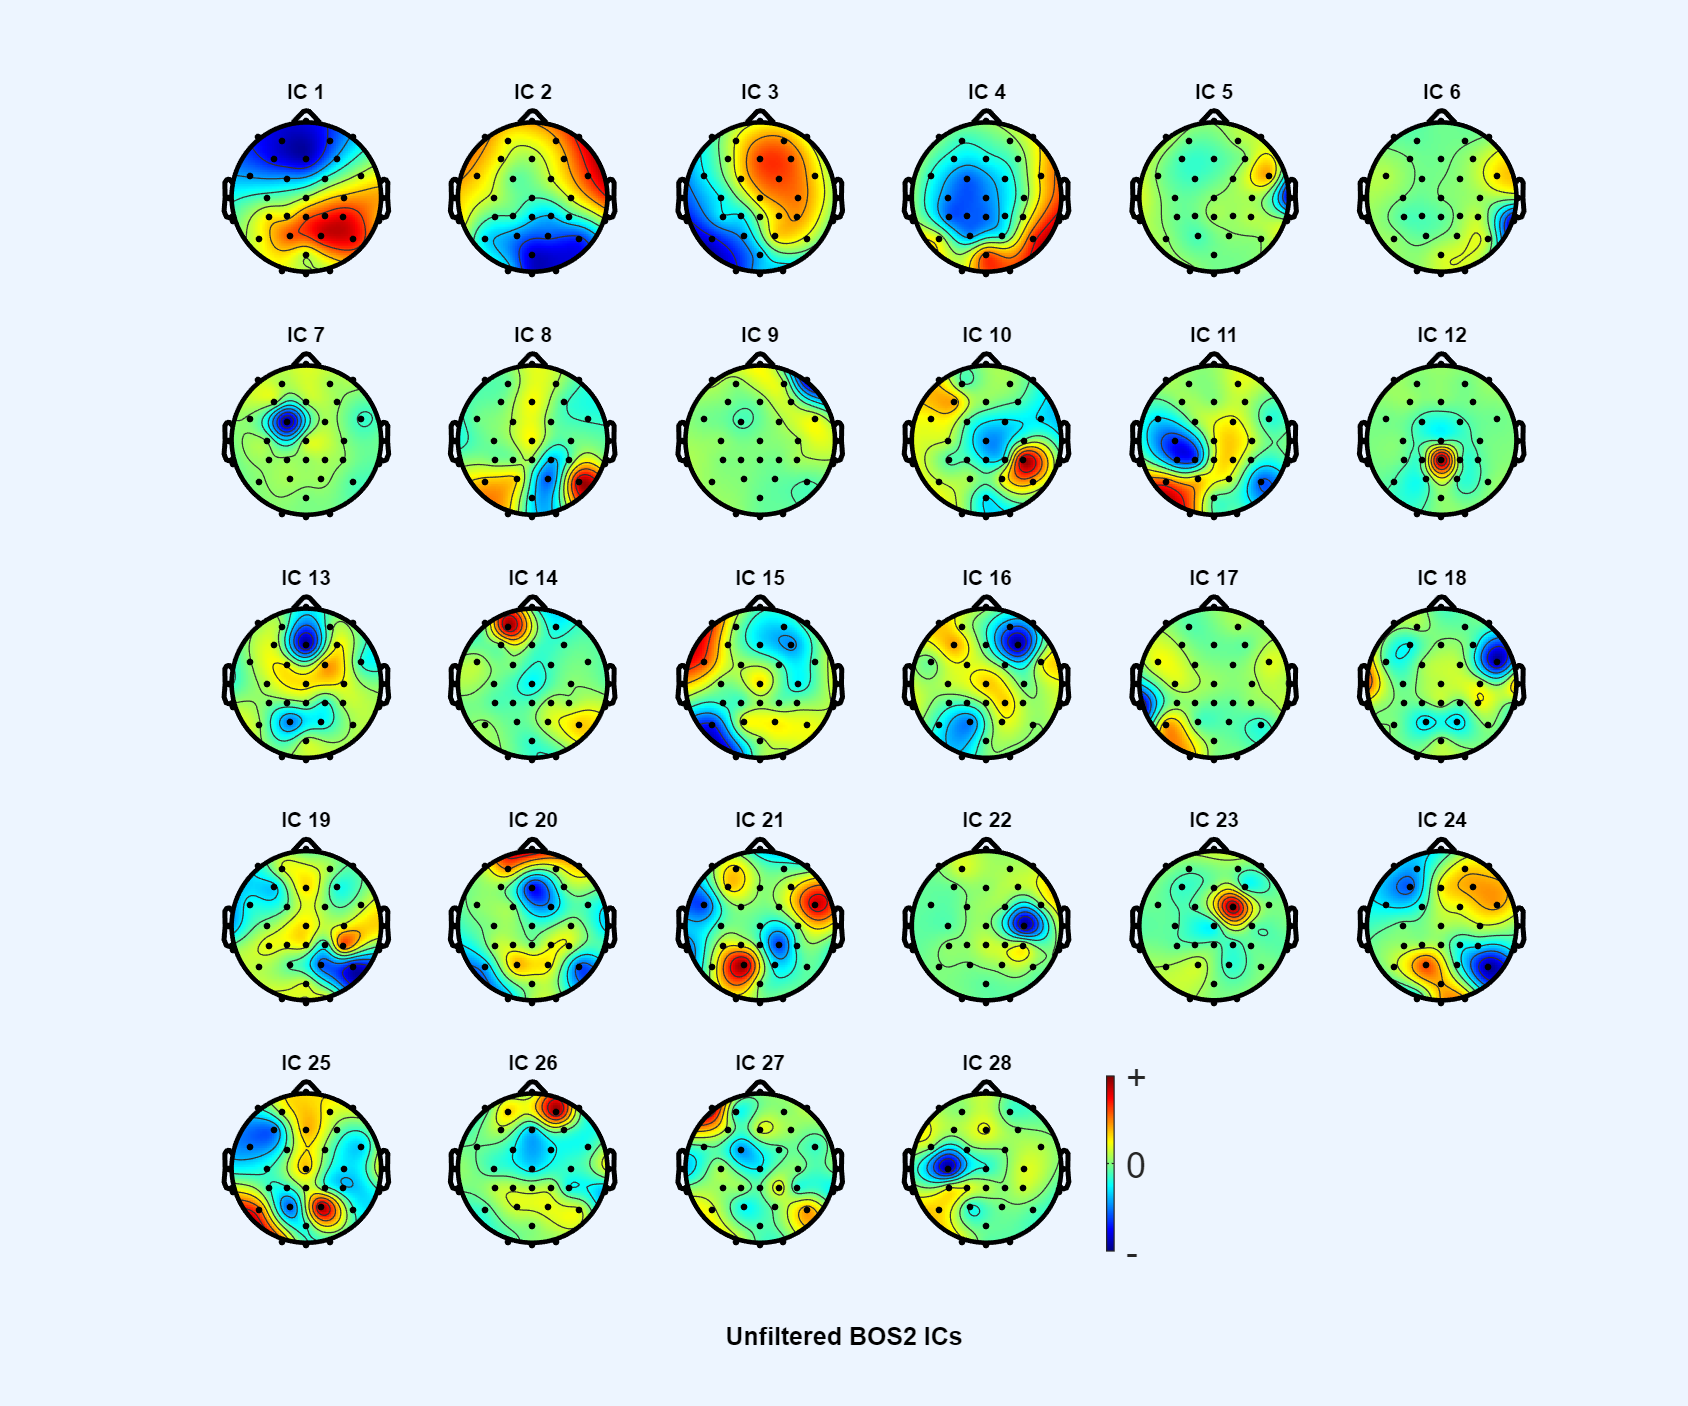

Plotting...


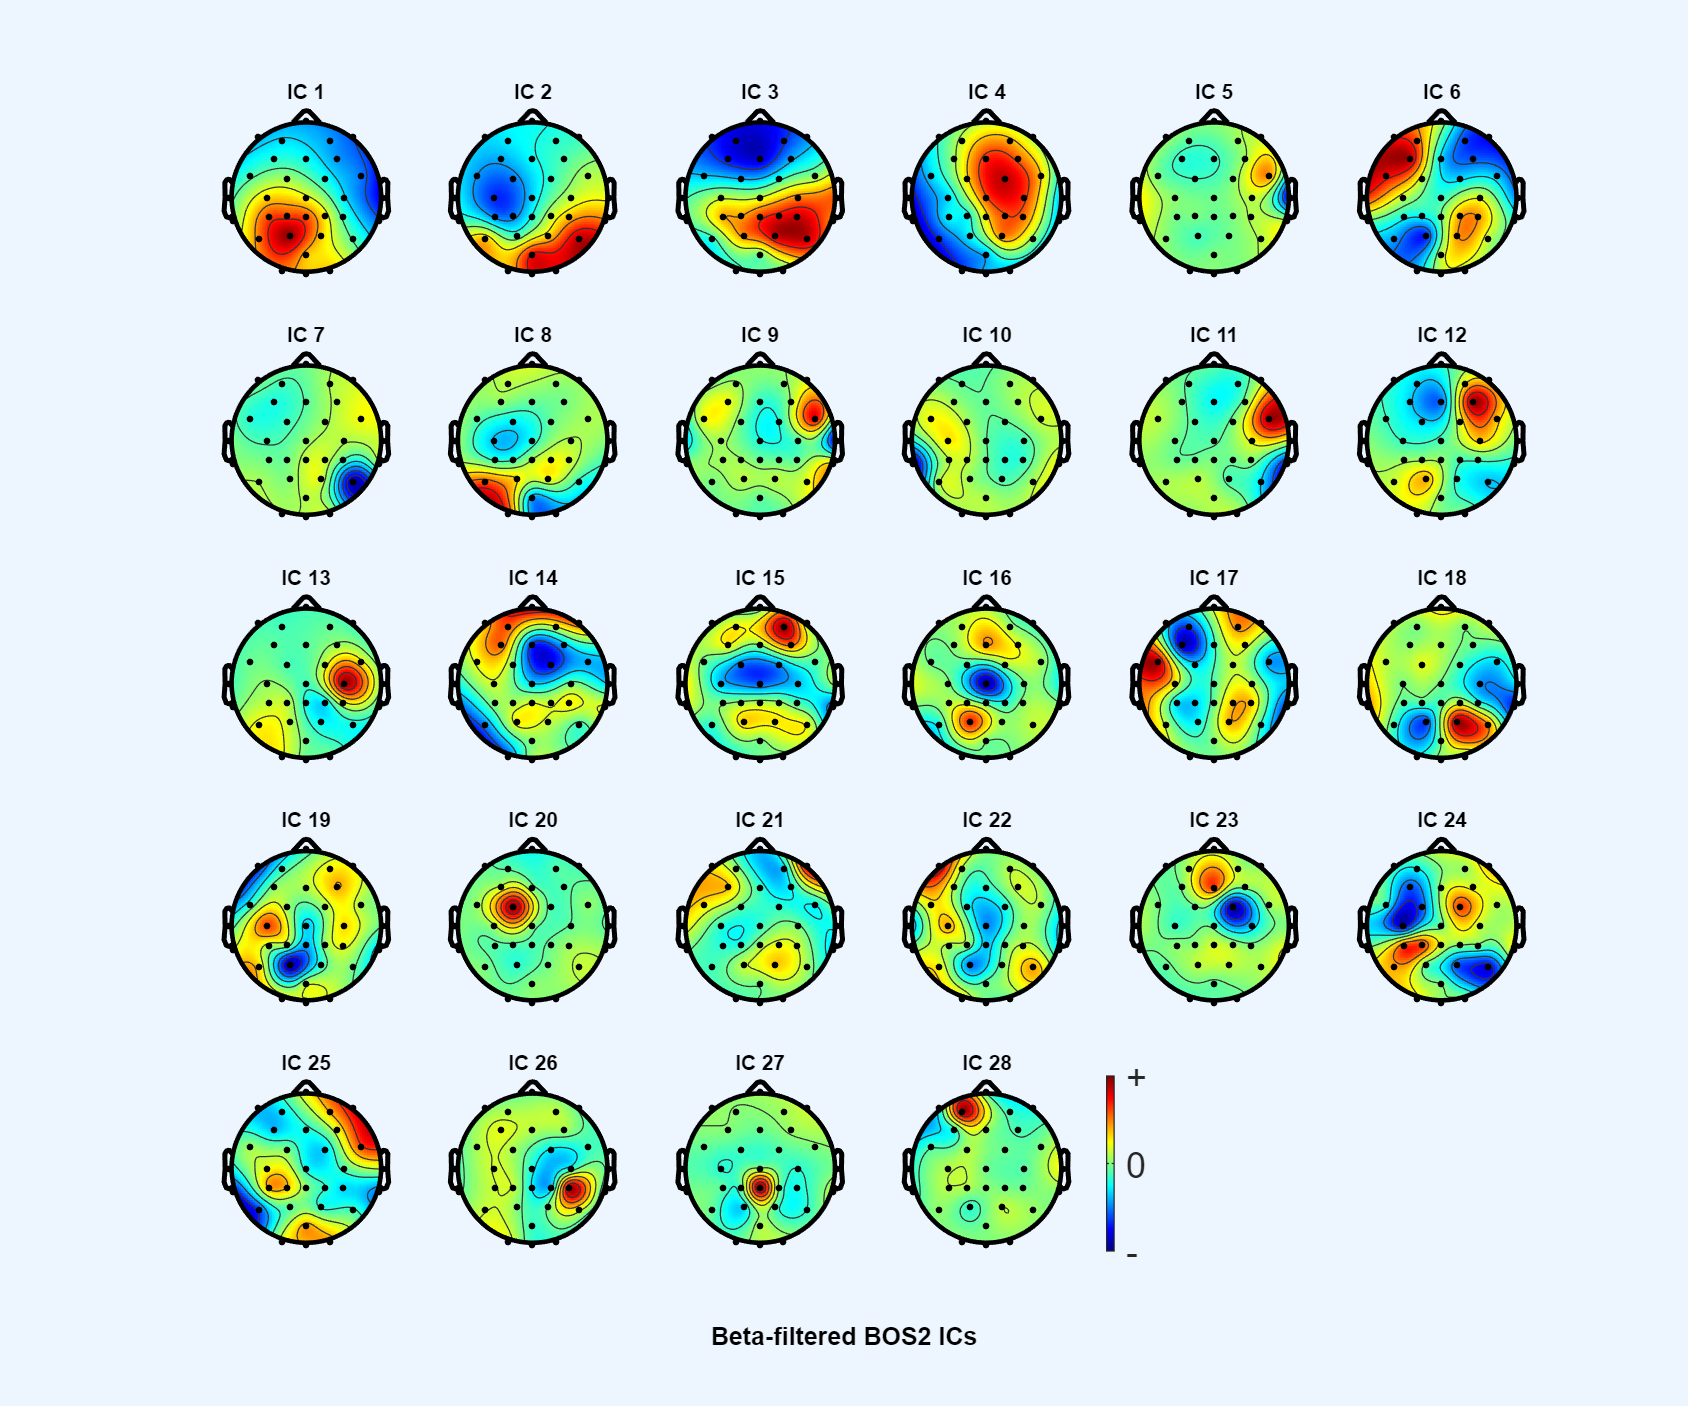

% % Project 4D data back into IC space: This gives you the IC activations as a 4D tensor, preserving trial and condition structure.
% X_2D = reshape(X, ch, []);
% IC_activations = W * X_2D;  % W is ICA unmixing matrix
% IC_tensor = reshape(IC_activations, size(W,1), time, trials, conds);


## Helper function to find the file for a specific subject

function file_idx = find_subject_file(set_files, subject_id)
    file_idx = 0;
    for i = 1:length(set_files)
        filename = set_files(i).name;
        % Check if the subject ID (e.g., "BOS2") is part of the filename.
        % This is a more robust check than relying on specific parts or delimiters.
        if contains(filename, subject_id)
            file_idx = i;
            return; % Return as soon as a match is found
        end
    end
    % If loop completes, no match was found, file_idx remains 0.
end